clear variable
close all

sigmax=spinOp(5/2,'x');
sigmay=spinOp(5/2,'y');
sigmaz=spinOp(5/2,'z');
initial=[1 0 0 0 0 0]';
rot=sigmay^2;
precession=sigmax;
timelist=[0:0.01:4].*pi;

## Rabi

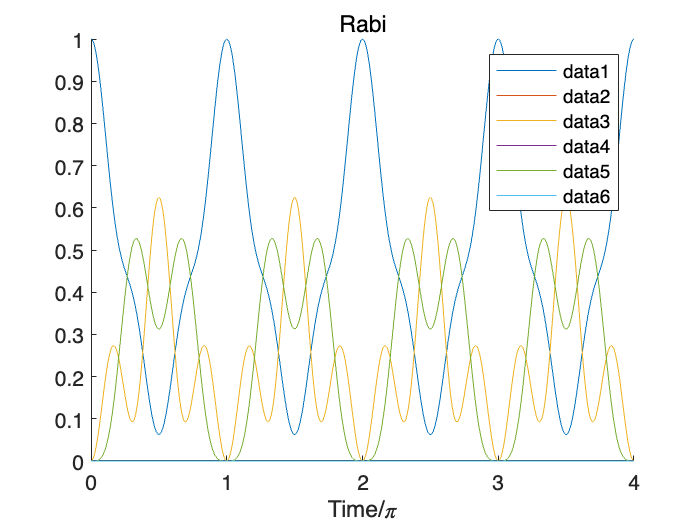

for i=1:length(timelist)
    rabi(:,i)=solve_ham(rot,initial,timelist(i));
end

population_rabi=abs(rabi).^2;
figure;hold on;

for i=1:6
    plot(timelist./pi,population_rabi(i,:));
end
legend;
xlabel('Time/\pi');
ylim([0 1]);
title('Rabi')

## Ramsey

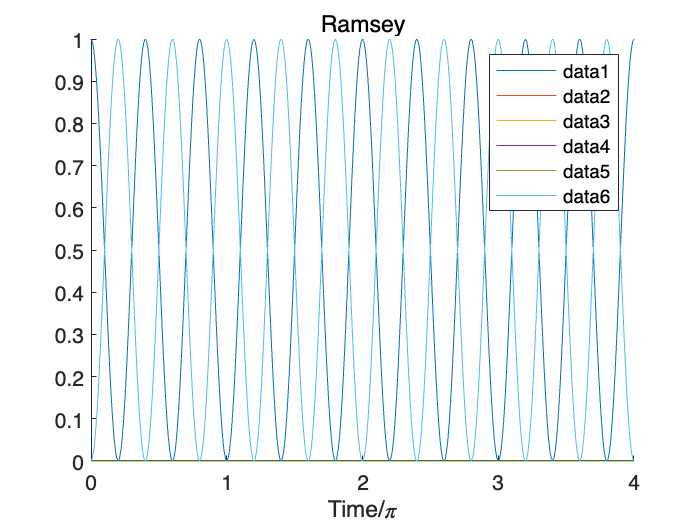

cat_1=solve_ham(rot,initial,pi/2);
for i=1:length(timelist)
    cat_2=solve_ham(precession,cat_1,timelist(i));
    detect(:,i)=solve_ham(rot,cat_2,3*pi/2);
end

population=abs(detect).^2;
figure;hold on;

for i=1:6
    plot(timelist./pi,population(i,:));
end
legend;
xlabel('Time/\pi');
ylim([0 1]);
title('Ramsey')

function final=solve_ham(ham,initial,time)
    final=expm(-ham.*time.*1i)*initial;
end